**Define Communication Parameters**

freq = [1:1000]*1e9; % Range of EHF frequencies
R1 = 6e3; % Path distance in km Troposphere Low
R2 = 20e3; % Path distance in km Trophophere High
T = 15; % Temp of 15 degrees Celcius
P = 101300.0; % Pressure in Pascals
W = 7.5; % Water vapor density in g/m^3

**Compute Attenuation for Troposphere of 6,000 m (poles)**

L1 = gaspl(R1, freq, T, P, W);

**Compute Attenuation for Troposphere of 20,000 m (equator)**

L2 = gaspl(R2, freq, T, P, W);

**Plot Atmospheric Attenuation**

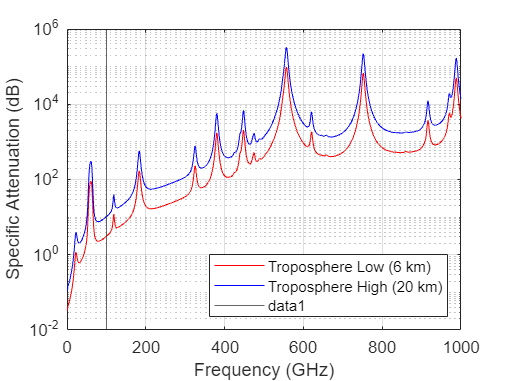

semilogy(freq/1e9, L1, 'r')
hold on
semilogy(freq/1e9, L2, 'b')
legend('Troposphere Low (6 km)', 'Troposphere High (20 km)', 'Location', 'southeast')
xlabel('Frequency (GHz)')
ylabel('Specific Attenuation (dB)')
grid on
xline(100)
hold off

**Plot Actual Atmospheric and Free Space Attenuation**

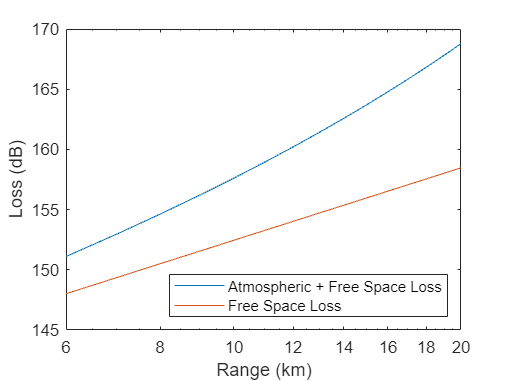

ranges = [6:20]*1e3;
wBandFreq = 100e9;
gasLosses = gaspl(ranges, wBandFreq, T, P, W);
lambda = physconst('LightSpeed')/wBandFreq;
FSL = fspl(ranges, lambda);
semilogx(ranges/1000,gasLosses + FSL.',ranges/1000,FSL)
legend('Atmospheric + Free Space Loss','Free Space Loss','Location','southeast')
xlabel('Range (km)')
ylabel('Loss (dB)')

grid on